clear; clc; 
close all;

## 1. Binarization

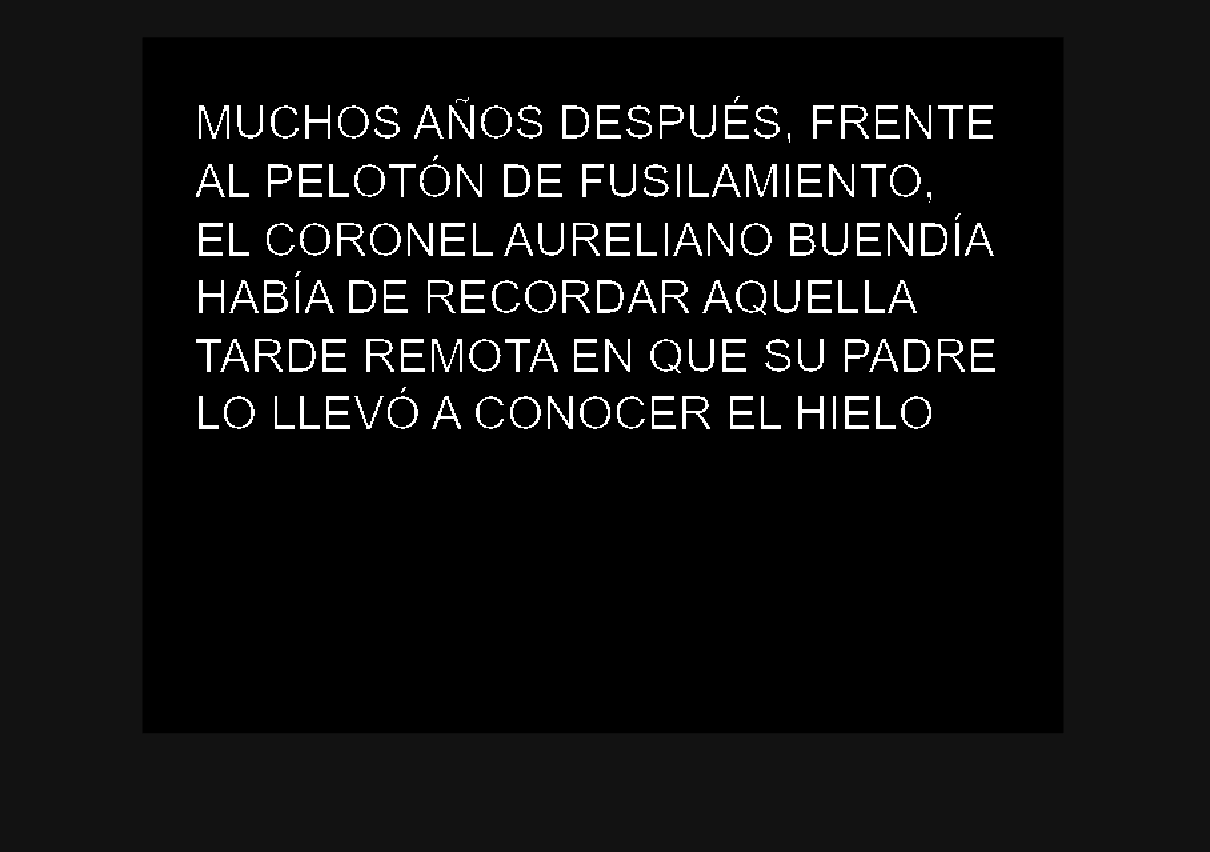


task1Binarization('im1.png', 0.01);

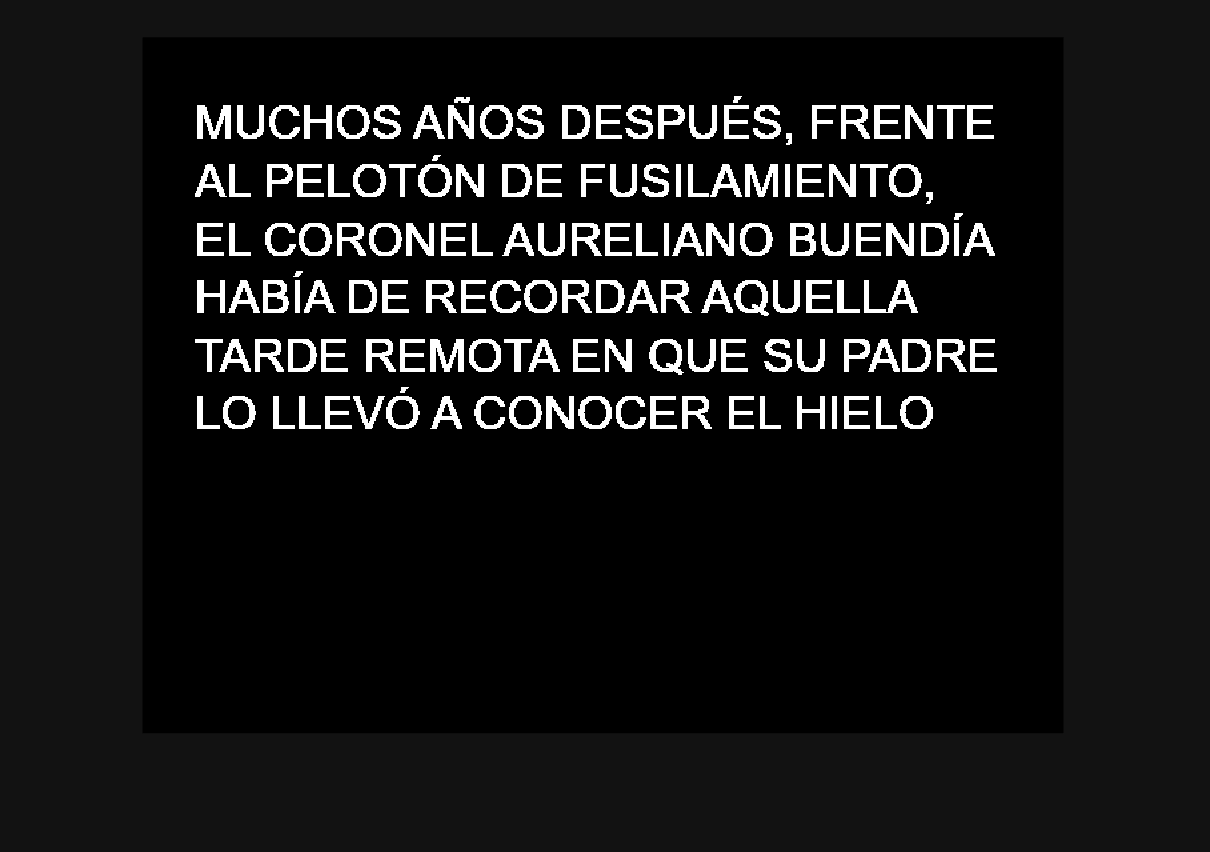

task1Binarization('im1.png', 0.99);

Lower threshold = líneas más finas, capta menos. A mayor theshold, mayor densidad de píxeles que ha captado. Otsu finds the optimal  threshold.

imBinarized = task1BinarizationAdvanced('im1.png');

Otsu threshold: 0.506


%imshow(imBinarized); %solo para testeo, LUEGO QUITAR

## 2. Segmenting Rows

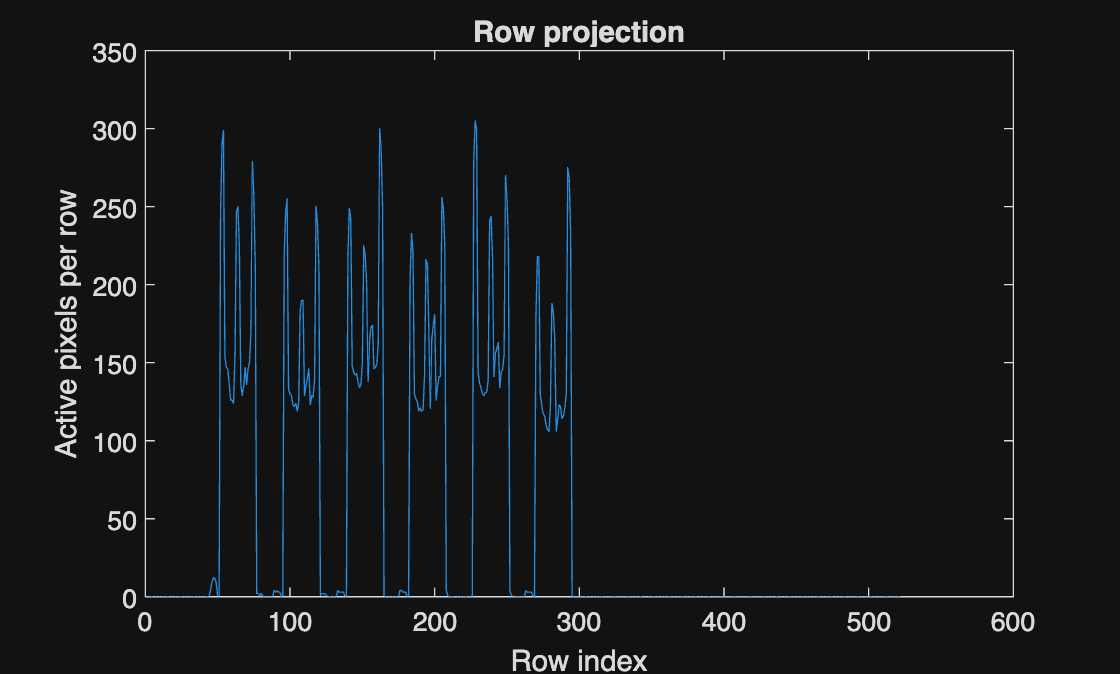


% Method: vertical projection
% Sum image rows to detect text lines
rowProjection = task2RowProjection(imBinarized); 

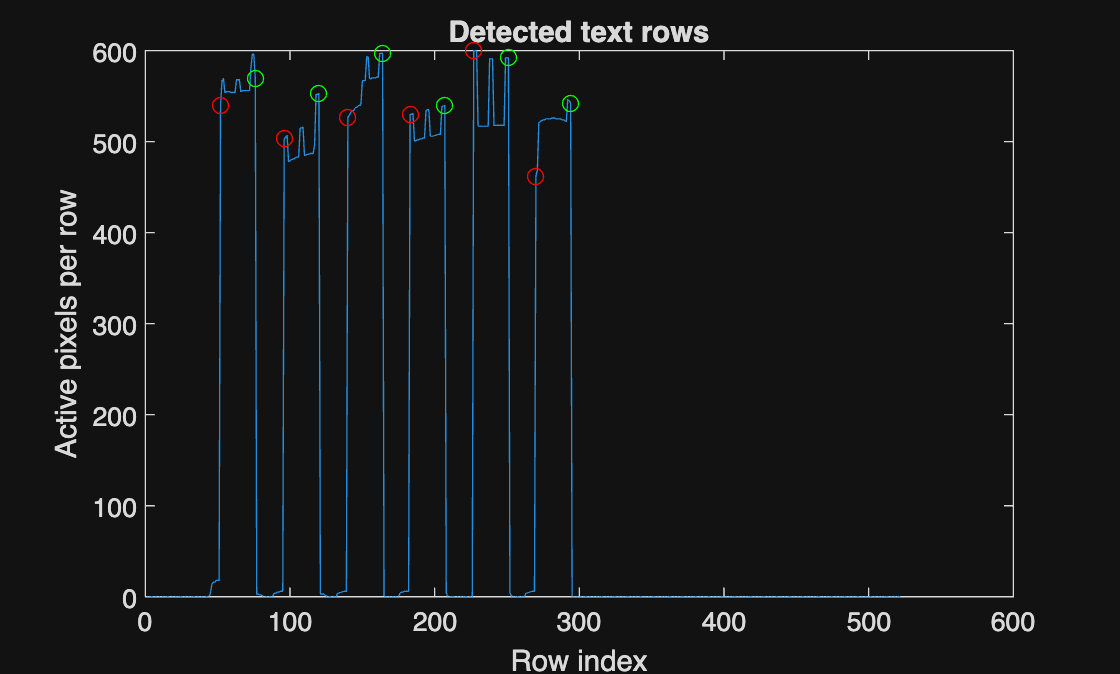


[rowStarts, rowEnds, rowMask] = task2SegmentRows(imBinarized);


rowImages = task2ExtractRows(imBinarized, rowStarts, rowEnds);


## 3. Segmenting Characters

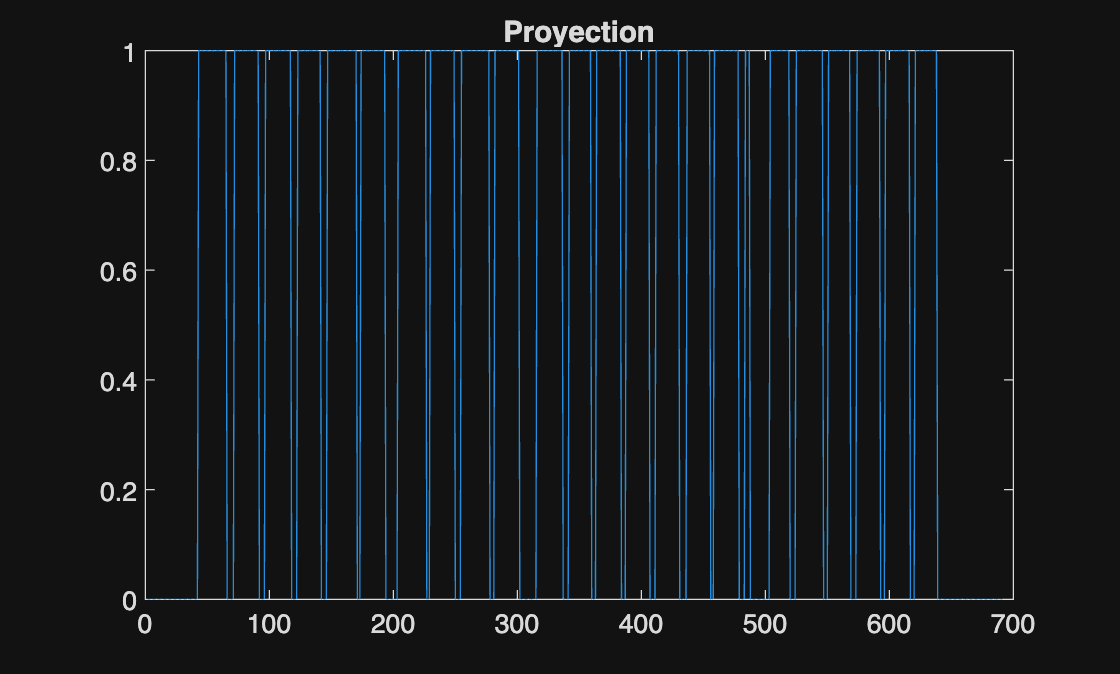

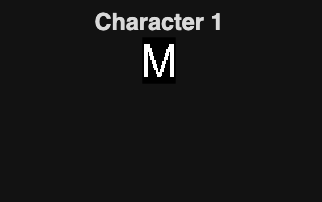

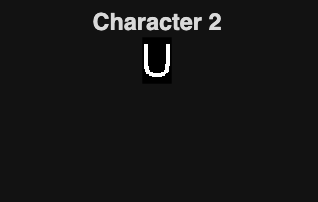

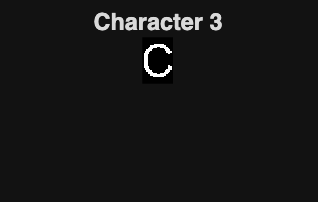

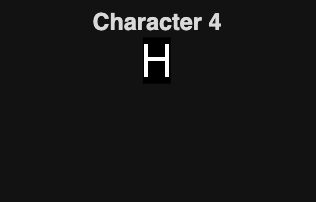

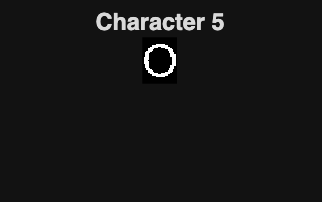

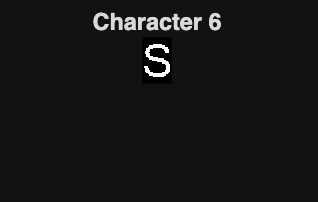

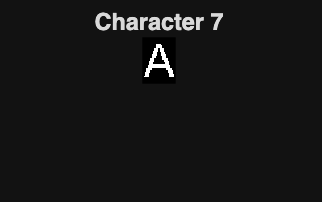

numRows = length(rowImages);
allChars = cell(numRows, 1); %por que nuestra funcion trabaja con celdas y rowImages es una matriz
for i= 1:numRows
    characterInd = task3SegmentCharacters(rowImages{i});
    allChars{i} = characterInd;
end

## 4. Preprocessing Characters

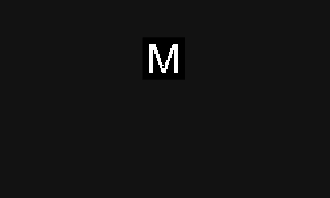

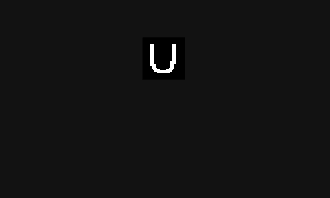

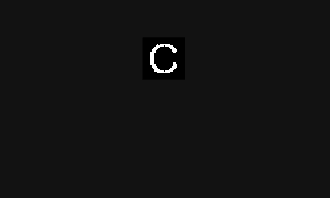

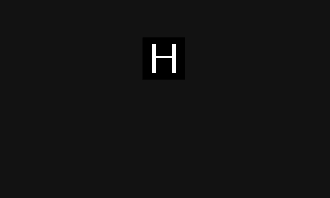

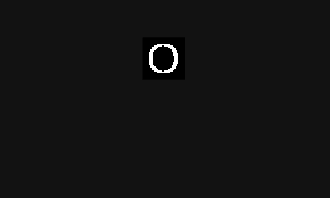

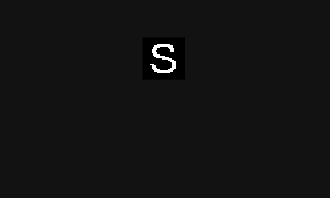

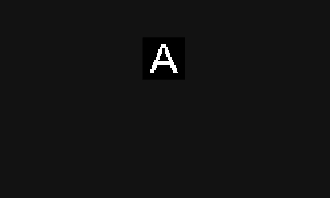

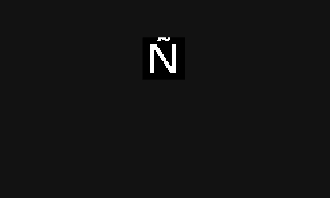


imResize = task4PreprocessingCharacters(allChars,32);

## 5. Creating Alphabet

[alphabet, alphabetChars] = task5CreatingAlphabet('alphabet.png', 32, 'ABCDEFGHIJKLMNOPQRSTUVWXYZ');

Otsu threshold: 0.522
